# Effect of Haar-Based Compression on Virtual Reality Images

### Final Project for Math 179 (Spring 2019)

### Yoshiki Takashima (A14691595)

## 1. Overview

Traditionally, an image represents a 2-Dimensional uniform grid of pixels. On the other hand, with the rise of Virtual Reality (VR) technologies, various methods were created to project a 3-Dimensional sphere onto one or more images. Furthermore, due to the mathematical difficulty of projecting a 3-Dimensional image onto 2-Dimensional formats, these images are naturally skewed. In these use cases, the image no longer represents the traditional rectangular format, even as the encoding is the same. I will explore the effect of traditional (2-Dimensional) compression techniques on Equirectangular VR images. Furthremore, we will implement the previously mitigations proposed for Equirectangular images. To provide comparison with other methods, we will also compress VR images mapped in the Cube Map format and the recently proposed Equiangular Cube Map format. We will end with comparison of compression artifacts between various mapping formats and the theory behind why these artifacts occur.

Before we start, let us introduce the mapping formats. In its natural format, the VR image is a sphere. First, the **Equirectangular Mapping** is the most simple mapping. This mapping projects the spere onto a cylinder and rolls it out, resulting in an image that is stretched at the margins. Second is the **Cube Mapping**. This mapping projects the sphere onto a cube, and cuts out the image to a set of 6 images representing the views of each direction. Third, **Equiangular Cube Mapping** is a mapping format recently presented by Google, which uses new sampling techniques to reduce image skewing for improved quality, especially in VR video applications. In addition to the above three, which we will experiment with, various other mappings have been presented, including the pyramid mapping used by Facebook.

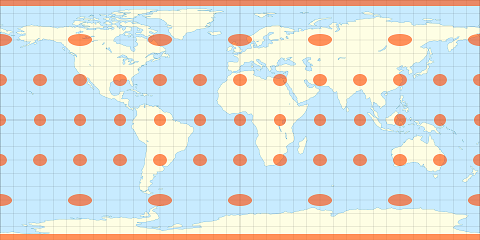

Equirectangular Mapping of the world map.

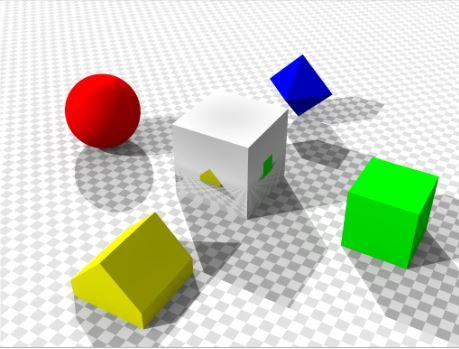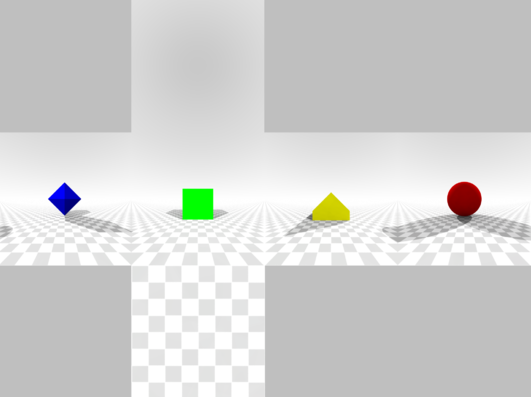

A VR environment (left) and a cube mapping using the middle cube as the perspective (right).

Project Content and Artifacts:

- Matlab implementation of recently discussed compression methods.

- Matlab implementation of converters between formats.

- Comparison of compression artifacts in various formats.

Note: A custom HTML based virtual reality viewers are also included. However, this uses libraries/copied code heavily and should not be counted for the project.

## 2. Recent and Related Works

Most of the recent works in this field date back 2016~18 period, occuring simulataniously with the mass commercialization of VR technologies. As noted before, Google's Equiangular Cube Mapping (Brown, 2017) was a direct response to resolution issues in VR images with application in video streams. By enforcing the equiangular property on the sampling, this technique ensures that the information is more equally distributed. The pyramidal mapping proposed by Facebook (Kuzyakov and Pio, 2016) converts Equirectangular video into "30 viewports, and ... create five different resolutions for each stream," allowing an approximately smooth transition between the viewports. For standards, Moving Picture Experts Group's Omnidirectional Media Format (MPEG OMAF) standard, albeit more generally oriented toward VR video streams, is one standard that use packing based on image regionand adaptive compression using other factors like the user's head position. 

## 3. Pipeline Setup and Formats

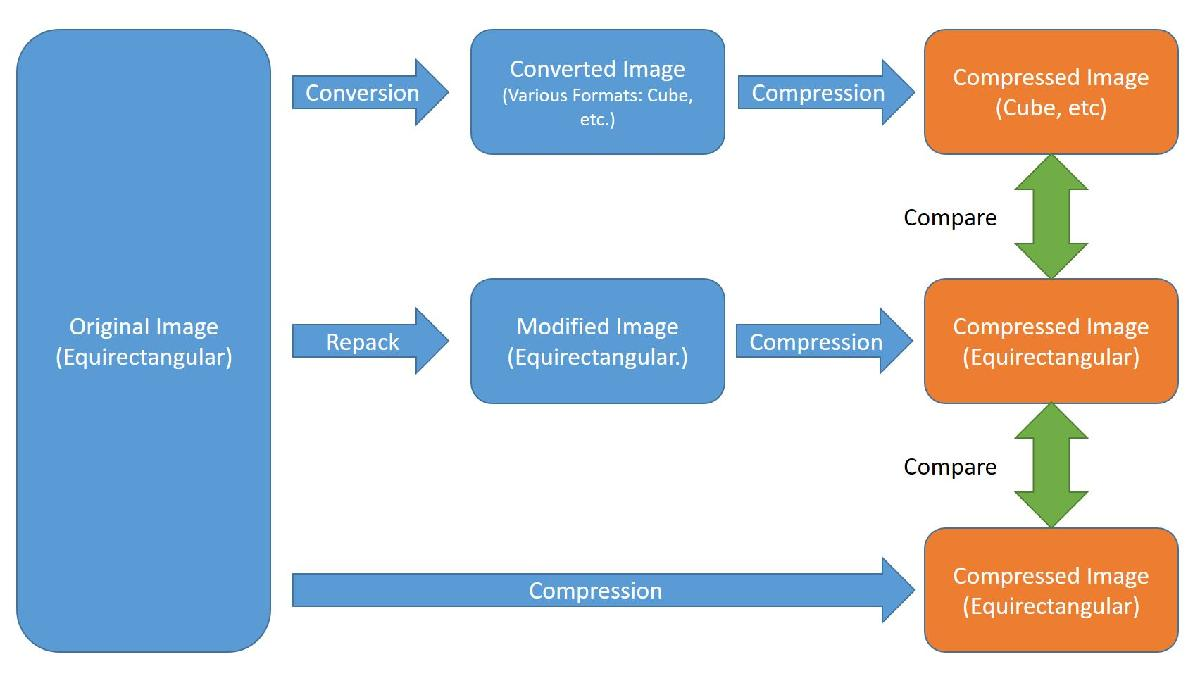

Since we are comparing quality, we must follow a standard procedure for consistency. All images we deal with are in JPEG format and resized to powers of 2. Furthermore, they will be originally in the Equirectangular mapping, and converted to other mappings if necessary. This is because this is the most widely available format for me. Comparisons will be done between the various compressed images in the VR viewer (filename.html). 

## 4. Equirectangular Mapping

First, let us try to apply compression naively. We will simply take the image and do a Haar-based elimination of detail for each RGB channel. The compression ratio here is 5:1 and we add noise to remove the compression effects. 

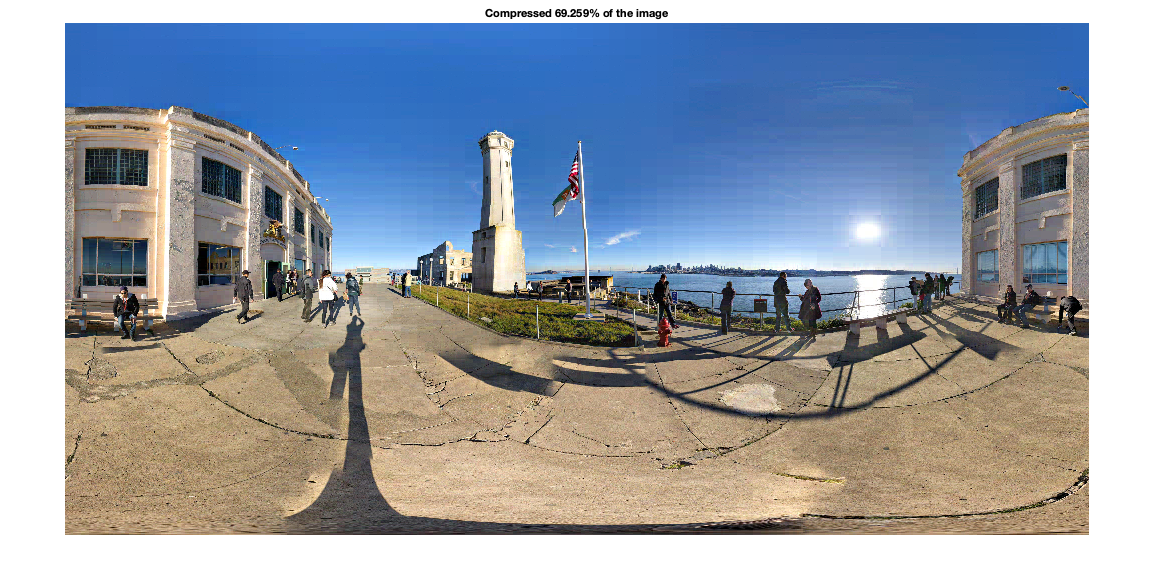

clear;
image = imread('Viewers/Original360/Alcatraz.jpg');
before=dir('Viewers/Output360/Alcatraz.jpg');
sizeBeforeComp = before.bytes;

[image(:,:,1), d1] = Compression(image(:,:,1),4);
[image(:,:,2), d2] = Compression(image(:,:,2),4);
[image(:,:,3), d3] = Compression(image(:,:,3),4);

imwrite(image, 'Viewers/Output360/Alcatraz.jpg');
imshow(image);
title("Compressed " + num2str(100*mean([d1,d2,d3])) + "% of the image");

From the outside, this looks okay. 

However, when we view this image in the VR viewer, we see. 

## 5. Cube Mapping

## 6. Comparisons

## 7. Conclusion

## 8. References

- [https://www.vr-if.org/wp-content/uploads/VRSTD-01-MPEG-OMAF-Youngkwon-Lim.pdf](https://www.vr-if.org/wp-content/uploads/VRSTD-01-MPEG-OMAF-Youngkwon-Lim.pdf)

- [https://pdfs.semanticscholar.org/113d/0d0b44f5fc9ef52120cb57107626b1d5f69c.pdf](https://pdfs.semanticscholar.org/113d/0d0b44f5fc9ef52120cb57107626b1d5f69c.pdf)

- [https://blog.google/products/google-ar-vr/bringing-pixels-front-and-center-vr-video/](https://blog.google/products/google-ar-vr/bringing-pixels-front-and-center-vr-video/)

- [https://code.fb.com/virtual-reality/next-generation-video-encoding-techniques-for-360-video-and-vr/](https://code.fb.com/virtual-reality/next-generation-video-encoding-techniques-for-360-video-and-vr/)

- [https://stackoverflow.com/questions/44378186/a-frame-not-picking-up-a-cubemap](https://stackoverflow.com/questions/44378186/a-frame-not-picking-up-a-cubemap)

- [https://hackernoon.com/create-a-360-vr-supported-web-experience-in-under-5-minutes-bf3886cdb1c6](https://hackernoon.com/create-a-360-vr-supported-web-experience-in-under-5-minutes-bf3886cdb1c6)

- "Alcatraz 360°," "Toronto City Hall Square 360°," Stig Nygaard (Creative Commons)